%Kai Brown and Kevin Pogrund
%BRWKAI001     PGRKEV001

% Question 1
C = 37;
F = (9*C)/5 +32

F = 98.6000

% Question 2
N = [1 2 3 4 5];
a = 2.*N

a =      2     4     6     8    10


b = N./2

b =     0.5000    1.0000    1.5000    2.0000    2.5000


c = 1./N

c =     1.0000    0.5000    0.3333    0.2500    0.2000


d=1./(N.^2)

d =     1.0000    0.2500    0.1111    0.0625    0.0400


%Question 3
sum = 0;
for i = 1:1000
    sum = sum + 1/i*(-1)^(i-1);
end
sum

sum = 0.6926

log(2)%pretty close

ans = 0.6931

%Quesion 4
xp = 1;
for i = 1:100
    if(rem(i+1,10)==0)
        xp = (10*xp)/i
    else
        xp = (10*xp)/i;
    end
end

xp = 2.7557e+03

xp = 82.2064

xp = 0.0113

xp = 4.9025e-08

xp = 1.6440e-14

xp = 7.2107e-22

xp = 5.8438e-30

xp = 1.1178e-38

xp = 6.0577e-48

xp = 1.0715e-57

%Question 5
syms x;
signal = piecewise(sin(x)>0, sin(x), 0)

$$signal = \left\{ \begin{array}{cl} \sin\left(x\right) & \text{ if }0<\sin\left(x\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

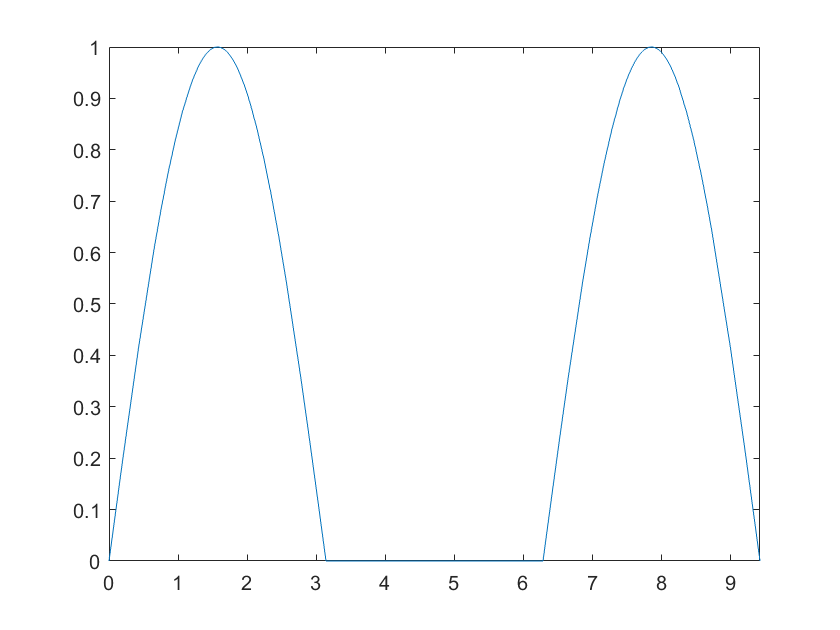

figure()
fplot(signal,[0, 3*pi])

%Question 6
roll = ceil(6*rand(1, 20));
prob = nnz(roll==6)/20

prob = 0.2500


roll = ceil(6*rand(1, 1000));
prob = nnz(roll==6)/1000

prob = 0.1480

1/6

ans = 0.1667

%Question 7
b = [1:7; 9:-2:-3; 2.^[2:8]]

b =      1     2     3     4     5     6     7
     9     7     5     3     1    -1    -3
     4     8    16    32    64   128   256


a = b(:,5)+b(:,7)

a =     12
    -2
   320


B = b(3,:)

B =      4     8    16    32    64   128   256


c=b;
temp = c(2,:);
c(2,:)=c(3,:);
c(3,:) = temp;
c

c =      1     2     3     4     5     6     7
     4     8    16    32    64   128   256
     9     7     5     3     1    -1    -3


%Question 8
v1 = [1 2 3 4 5];
v2 = [1;1;1;1;1];
a = v1.*v2

a =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


v3 = [0;1;2;3;4];
v4 = [1,1,1];
b = v3.*v4

b =      0     0     0
     1     1     1
     2     2     2
     3     3     3
     4     4     4


%Question 9
vx = 50:0.5:100; 
vy = 100:200;
%a)
misses = cannonBall(1000, 1250, 10, vx, vy)

misses =    50.0000  100.0000  893.4989
   50.0000  101.0000  885.2289
   50.0000  102.0000  876.9950
   50.0000  103.0000  868.7982
   50.0000  104.0000  860.6394
   50.0000  105.0000  852.5199
   50.0000  106.0000  844.4408
   50.0000  107.0000  836.4032
   50.0000  108.0000  828.4083
   50.0000  109.0000  820.4573


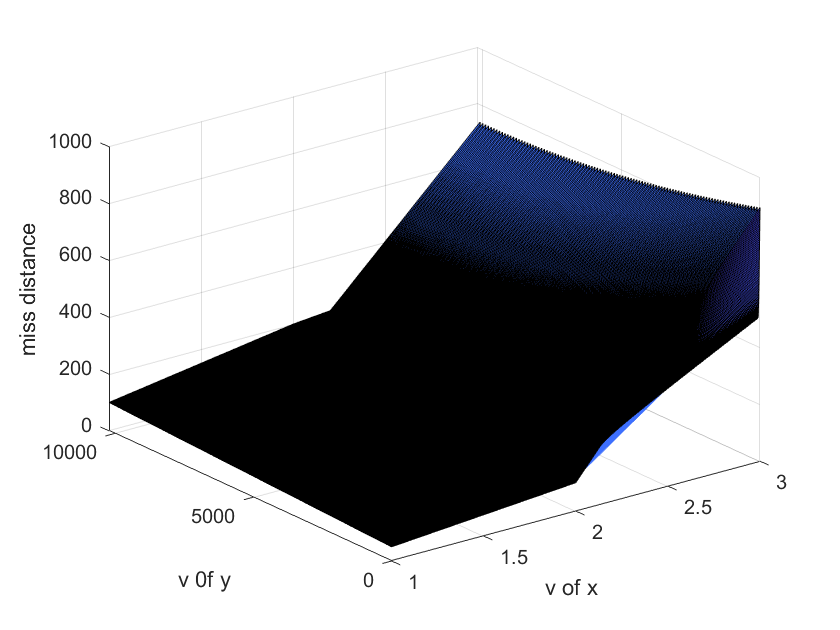


%c)
figure()
surf(misses);
xlabel("v of x");
ylabel("v 0f y");
zlabel("miss distance");


%d)
minMissDistance = min(misses(:,3))

minMissDistance = 0.5000

indMin = find(misses(:,3)==minMissDistance);
Vx = misses(indMin, 1)

Vx = 100

Vy = misses(indMin, 2)

Vy = 174

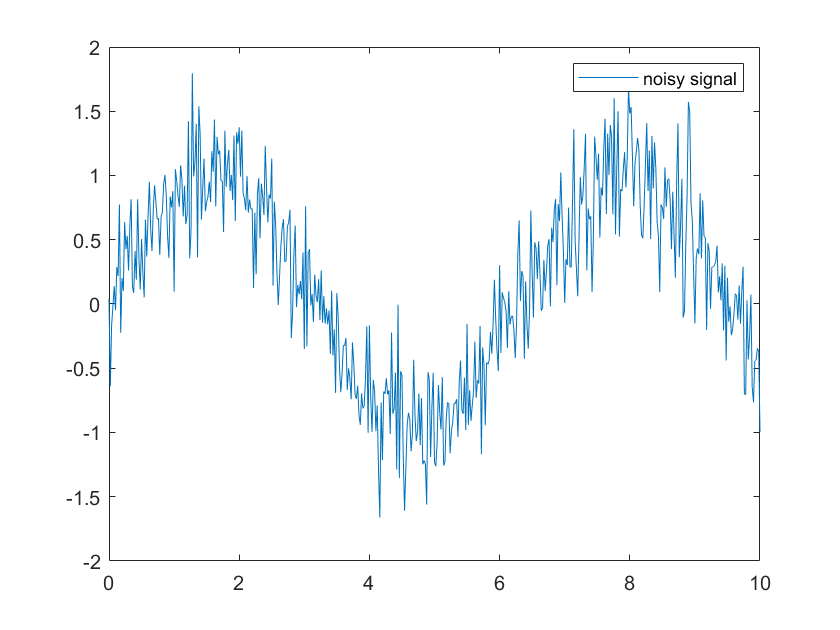

%Question 10
t = 0:0.02:10;
x = sin(t);
signal = awgn(x,10);
%a)
figure()
plot(t, signal)
%b)

legend('noisy signal')

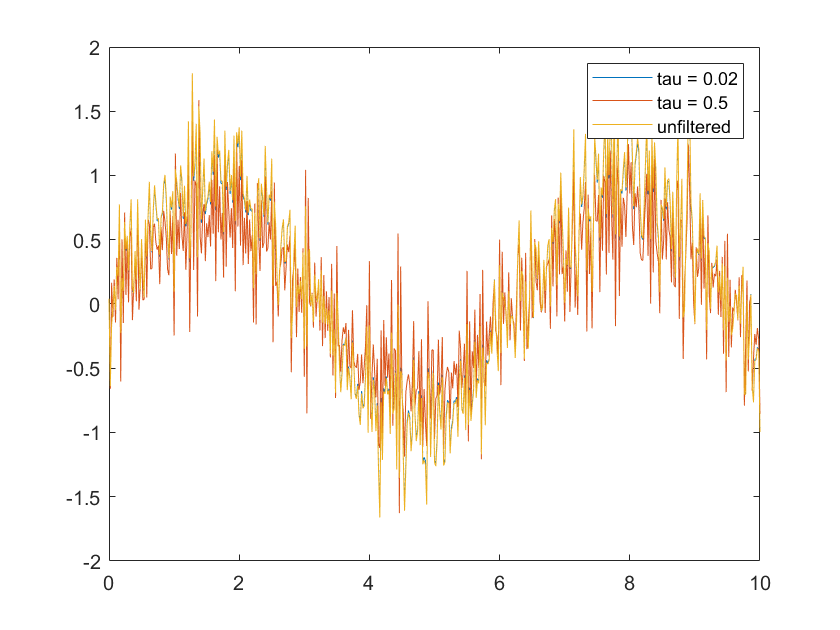

figure()
filt1 = filter(1, [1 0.02], signal);%tau = 0.02
filt2 = filter(1, [1 0.5], signal);%tau = 0.5
filt3 = filter(1, [1 1], signal);%tau = 1
plot(t, filt1)
hold on
plot(t, filt2)
plot(t, signal)
% plot(t, filt3)
legend('tau = 0.02', 'tau = 0.5', 'unfiltered', 'tau = 1')

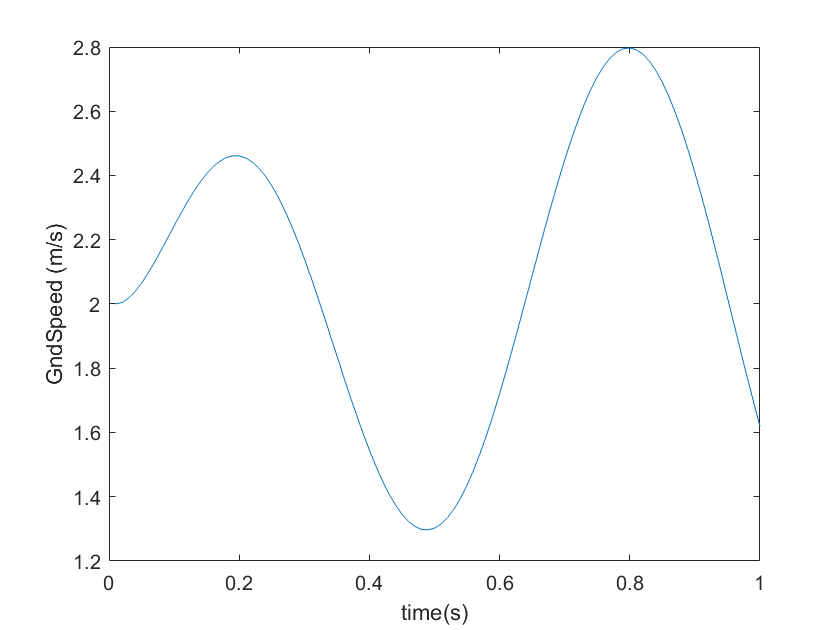

%Question 11
file = uiimport('EEE4119F - prac 1 - data.csv');

time = ones(length(GndSpeed),1);
for i = 1:length(GndSpeed)
    time(i,:) = 0.01*i; %10Hz
end
figure()
%a)
plot(time, GndSpeed)
xlabel('time(s)')
ylabel('GndSpeed (m/s)')


%b
[M, I] = max(GndSpeed);
topSpeed = M

topSpeed = 2.7971

timeOfMax = time(I,1)

timeOfMax = 0.8000


%c
acc = zeros(timeOfMax*100,1);
aveAcc = 0;
tot = 0;
for i = 2:length(acc)
    aveAcc = aveAcc+(GndSpeed(i)-GndSpeed(i-1))/0.01;
    %tot = tot+1;
end
aveAcc = aveAcc/timeOfMax

aveAcc = 168.6419

%Question 12

m = 1000;
b = 50;



%Question 9 function

function [dMiss] = cannonBall(xT,yT, t, vx, vy)
g = 9.81;

index = 1;
returnThis = zeros(length(vx)*length(vy),3);

for i = 1:length(vx)
    for j = 1:length(vy)
        xMiss = vx(i)*t -xT;
        yMiss = vy(j)*t-0.5.*g*t^2-yT;
        missedBy = sqrt(xMiss^2+yMiss^2);
        returnThis(index,:) = [vx(i),vy(j), missedBy];
        
        index = index +1;
    end
end
dMiss = returnThis;
end